# EKG Classification using Machine Learning and Simple Feature Extraction

This example shows how to classify human electrocardiogram (ECG) signals using Machine Learning algorithms. We will go through the workflow of (simple) feature extraction and training various machine learning models that can recognize the following heart rhythms:

- *Normal Sinus Rhythm*

- * Arrythmia*

The original ECG data comes from the PhysioNet 2017 Challenge, which is available at [https://physionet.org/challenge/2017/.](https://physionet.org/challenge/2017)

clear;

## Prepare Data

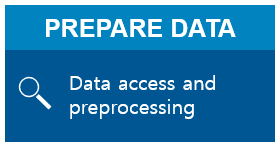

### Load and Preprocess Data

load PhysionetData.mat

This adds two variables to our workspace:

- `Signals` - cell array that holds ECG Signals

- `Labels` - categorical array that holds corresponding ground-truth labels

Signals(1:5)

ans = 5×1 cell array
    {[                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                   -127 -162 -197 -229 -245 -254 -261 -265 -268 -268 -267 -265 -263 -260 -256 -253 -249 -247 -245 -243 -241 -238 -236 -234 -232 -231 -230 -229 -229 -229 -229 -230 -230 -230 -229 -229 -227 -225 -221 -218 -215 -213 -213 -213 -212 -211 -210 -209 -206 -203 -201 -198 -198 -200 -204 -210 -216 -224 -233 -243 -253 -262 -270

Labels(1:5)

ans = 5×1 categorical array
     N 
     N 
     N 
     A 
     A 


summary(Labels)


Labels: 5788×1 categorical

     A                 738 
     N                5050 
     <undefined>         0 


As we can see in the preview, the signal length varies (see `Signals` variable). Let's create a [histogram](https://uk.mathworks.com/help/matlab/ref/matlab.graphics.chart.primitive.histogram.html) that shows the length of the signals.

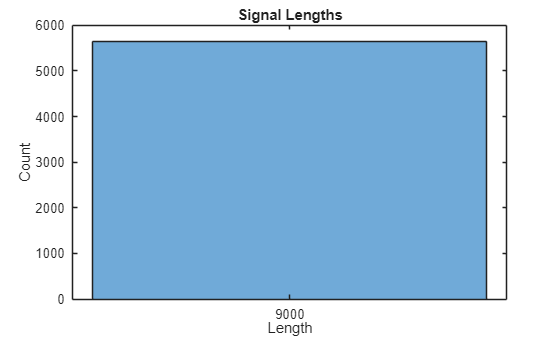

figure
plotSignalLengths(Signals)

Most of the ECG signals are 9000 samples long, but there is some variability.

Visualize a segment of one signal from each class.

Here are two common characteristics of AFib signals:

- Spaced out at irregular intervals.

- Lack a P wave, which pulses before the QRS complex in normal heartbeat.

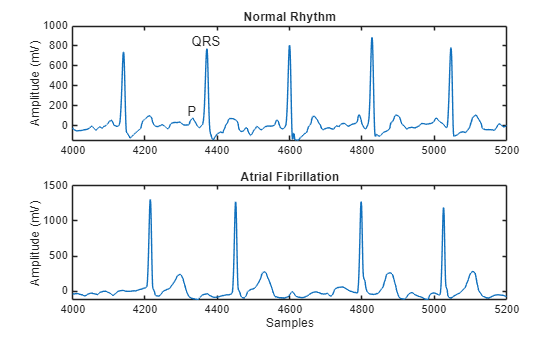

visualizeECGSignals(Signals)

Since the ECG Signals are different lengths, we need to first pad and truncate them so they are  all 9000 samples long. 

The function `segmentSignals` ignores signals with fewer than 9000 samples. If the signal is over 9000 samples, `segmentSignals` breaks it into as many 9000-sample segments as possible and ignores the remaining samples.

For example, a signal with 18500 samples becomes two 9000-sample signals and the remaining 500 samples are ignored.

[Signals,Labels] = segmentSignals(Signals,Labels);

Note: You can double check it by plotting the histogramm again.

### Feature extraction

Machine learning models use features (or predictors) as input (called dependent variables) and return a predicted value as the output (called independent variable). Features can be external measurements or any other values related to the output. The latter one can be seen as internal features which can be generated through transformation of the original data.

Extracting the best suitable features requires domain knowledge. Statistical measures of the data can be a good start to extract features. The best features are those that display a large difference between the different classes.

First, let's have a look at the distribution of the signals from both categories by plotting a histogram of one signal from each class. The helper function `plotBothHistograms` also calculates and displays the [median](https://uk.mathworks.com/help/matlab/ref/median.html), [standard deviation](https://uk.mathworks.com/help/matlab/ref/std.html), [skewness](https://uk.mathworks.com/help/stats/skewness.html), and [kurtosis](https://uk.mathworks.com/help/stats/kurtosis.html) of both signals and can be found at the end of the script.

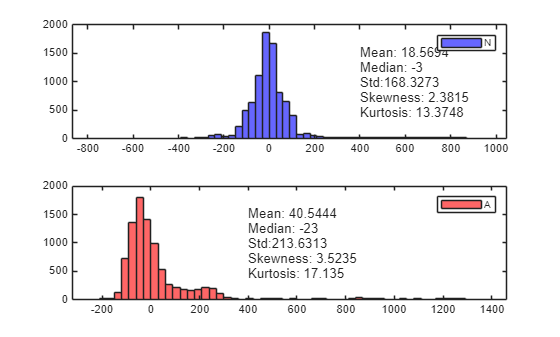

sig_norm = Signals(Labels=='N');
sig_afib = Signals(Labels=='A');

plotBothHistograms(sig_norm, sig_afib, Labels);

Judging by the statistical variables, it can be seen, that both signals (normal and afib) show very different characteristics. For this reason, we will be using these as features. We will also add [mean absolute deviation](https://uk.mathworks.com/help/stats/mad.html), 25 and 75 [quantiles](https://uk.mathworks.com/help/stats/quantile.html), and the signal [interquartile range](https://uk.mathworks.com/help/stats/prob.normaldistribution.iqr.html#:~:text=r%20%3D%20iqr(%20x%20)%20returns,the%20data%20contained%20in%20x%20.). The helper function `extractFeatures` calculates features for the entire data set.

(Note: Due to the large amoung of data this might take a couple of seconds.)

featuresTable = extractFeatures(Signals,Labels);

### Prepare Data for Training

In order to be able to evaluate the performance of the model/s, we split our data set into two subsets: a train set and a test set. The train set will be used to train the model/s while the test set will be used after the training to evaluate the performance on a new (unseen) data.

It is recommended to use between 60 and 90% of the entire data for training and the rest for testing.

One way to split the data is to use the [cvpartition](https://uk.mathworks.com/help/stats/cvpartition.html) command. In this example, we will use 80% of data for training and remaining for testing.

rng('default') % For reproducibility

N = length(featuresTable.class);

split_train_test = cvpartition(N, 'Holdout', 0.20);

idxTrain = training(split_train_test);
idxTest = test(split_train_test);

TrainData = featuresTable(idxTrain, :);
TestData = featuresTable(idxTest, :);

summary(TrainData.class)


4524×1 categorical

     A                 582 
     N                3942 
     <undefined>         0 


summary (TestData.class)


1131×1 categorical

     A                136 
     N                995 
     <undefined>        0 


## Train Model

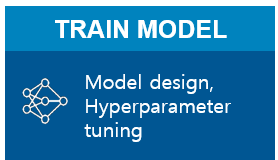

### Train using Classification Learner

One of the biggest challenges in machine learning is that there are many different machine learning algorithms that could be applied to the same problem, and there is no way of knowing ahead of time which will work best. The [Classification Learner App](matlab: web(fullfile(docroot, 'stats/classificationlearner-app.html'))) gives us an easy way to try out many different modeling techniques very quickly.

To open the Classification Learner App, you can either run the command below or go to APPS and click on  .

classificationLearner

Start a `New Session`

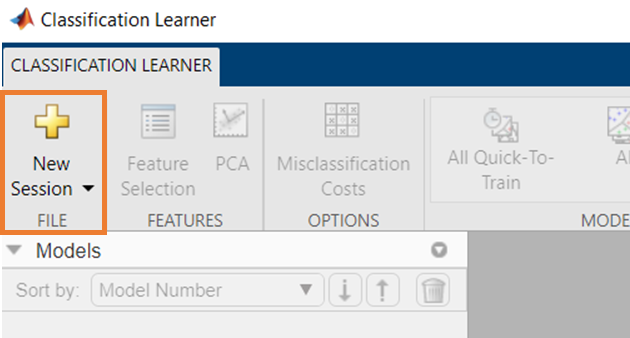

Choose `TrainData` variable from the workspace as your data. Make sure that `class` is selected as the `Response` and all tickboxes of the `Predictors` are ticked (except for `class`). Keep `Validation` section as it is (`Cross-Validation` with `5 folds`) and click on `Start Session`.

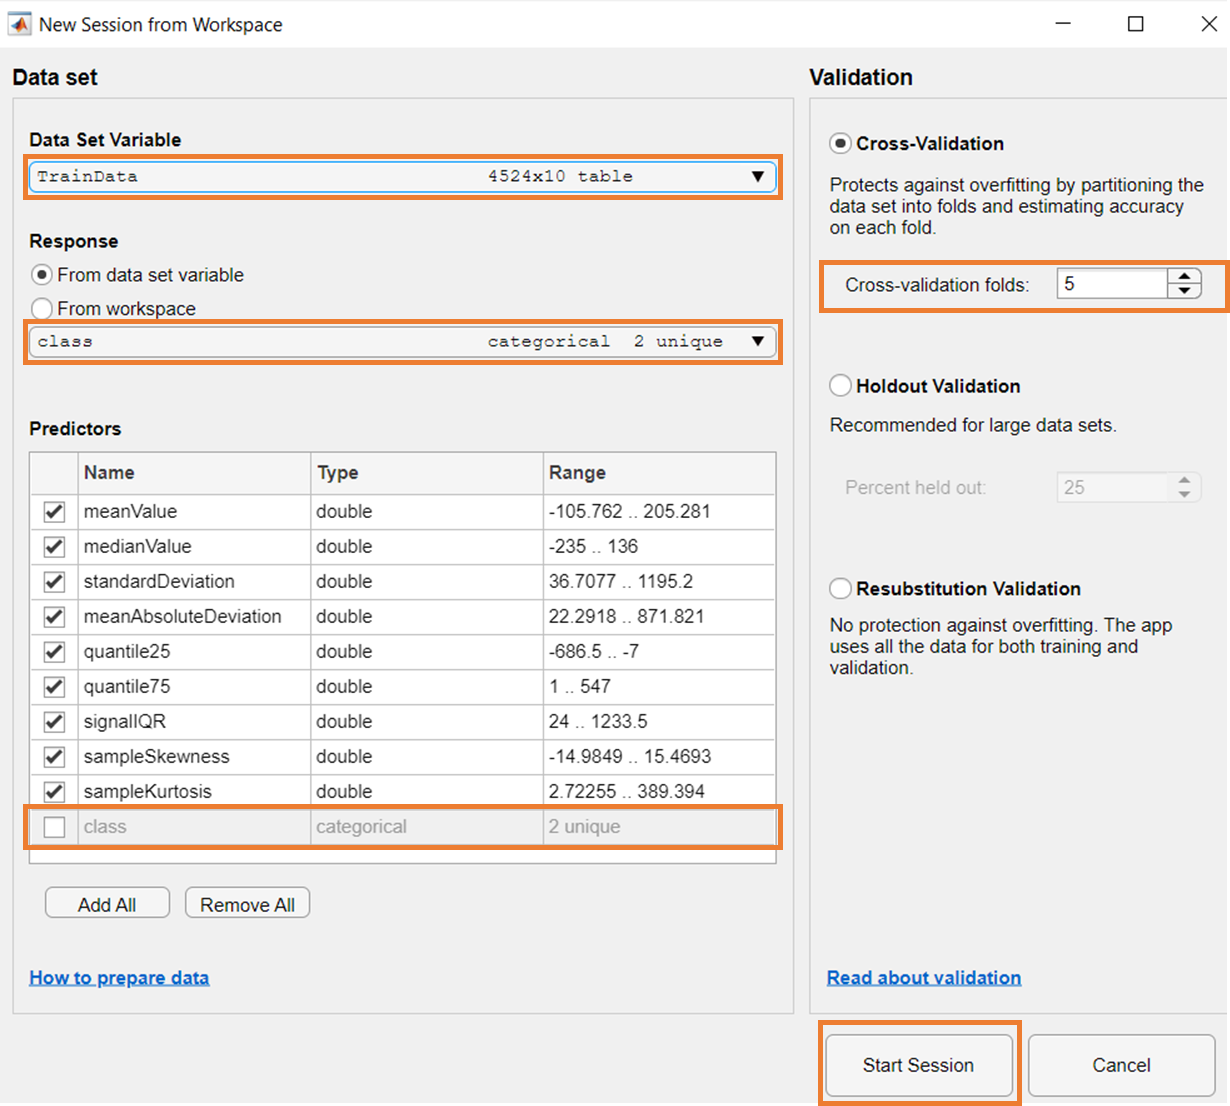

In `Model Type`, choose `All Quick-To-Train` and start training by clicking on `Run`. The training should take only a couple of seconds.

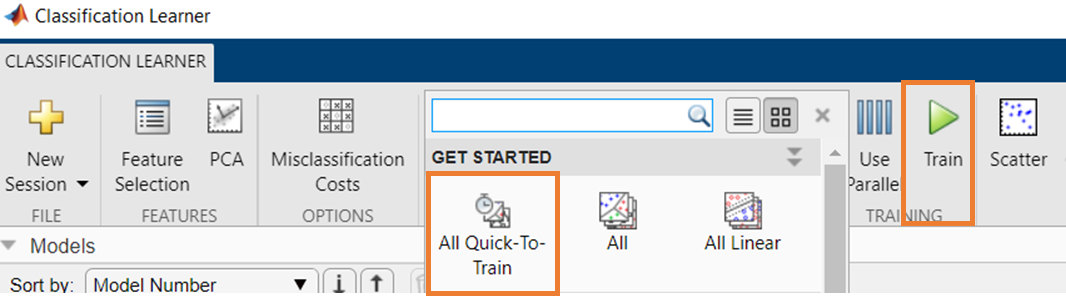

In the `Models `window, you should see the training progress and when done, the final accuracy of each model. The highest accuracy is highlighted in bold. Your results should look similar to this:

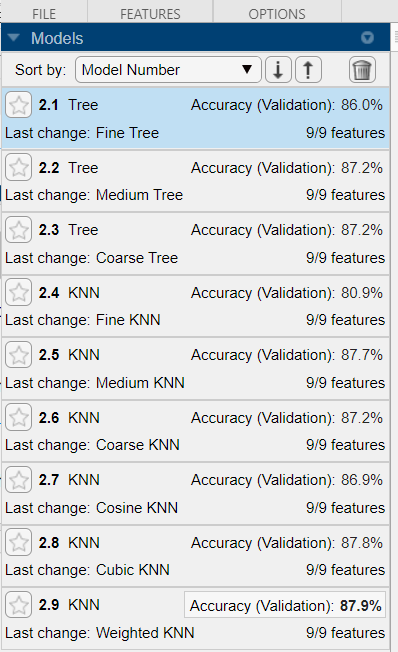

Explore the confusion matrices of each model by clicking on the individual model and on `Confusion Matrix.`

### Addressing Data Imbalance

Most of the trained models have a very hight false negative rate for the afib signal. This is due to the inbalance in the classes (remember the training set contains 582 afib singals and 3942 normal signals) which makes the model biased towards the major class (in our case the normal signal).

There are multiple ways how to handle imbalanced classes, such as for example appying the oversampling or undersampling techniques. Onether way to reduce the missclassification is to use cost-sensitive models which penalise the majority class. The Classification Learner App provides an option to specify the [Misclassification Costs](https://uk.mathworks.com/help/stats/misclassification-costs-in-classification-learner-app.html) matrix. Finding the best misclassification cost coefficients is often done manually by trial-and-error. 

- In `Model Type`, choose `All Quick-To-Train models` and modify the `Misclassification Costs`. The diagonals of the misclassification matrix have to be zero.

You might find that the false negative rate for the afib signal will reduce, however, it will increase for the normal signal. The overall accuracy will also most likely decrease (unless you found the right missclassification costs).

[Optional: Try to balance the data. You might find [this](https://uk.mathworks.com/help/stats/classification-with-unequal-misclassification-costs.html) and [this](https://uk.mathworks.com/help/stats/classification-with-imbalanced-data.html) useful.]

### Evaluating the trained model 

You can evaluate the performance of the each model on the new (unseen) data set.

Load the test data set by clicking on the `Test Data` dropdown menu and choosing `From Workspace `(select `TestData` as input) and click on `Import.`

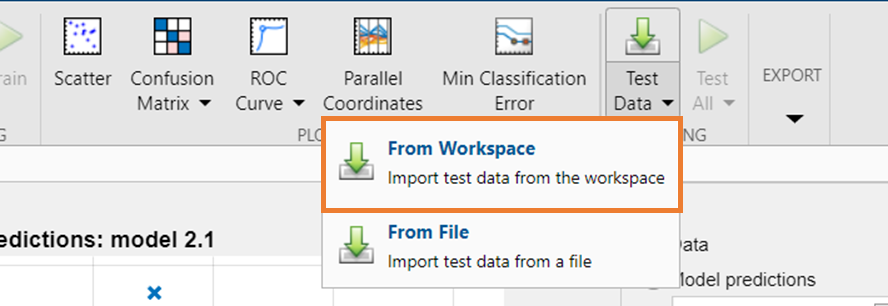

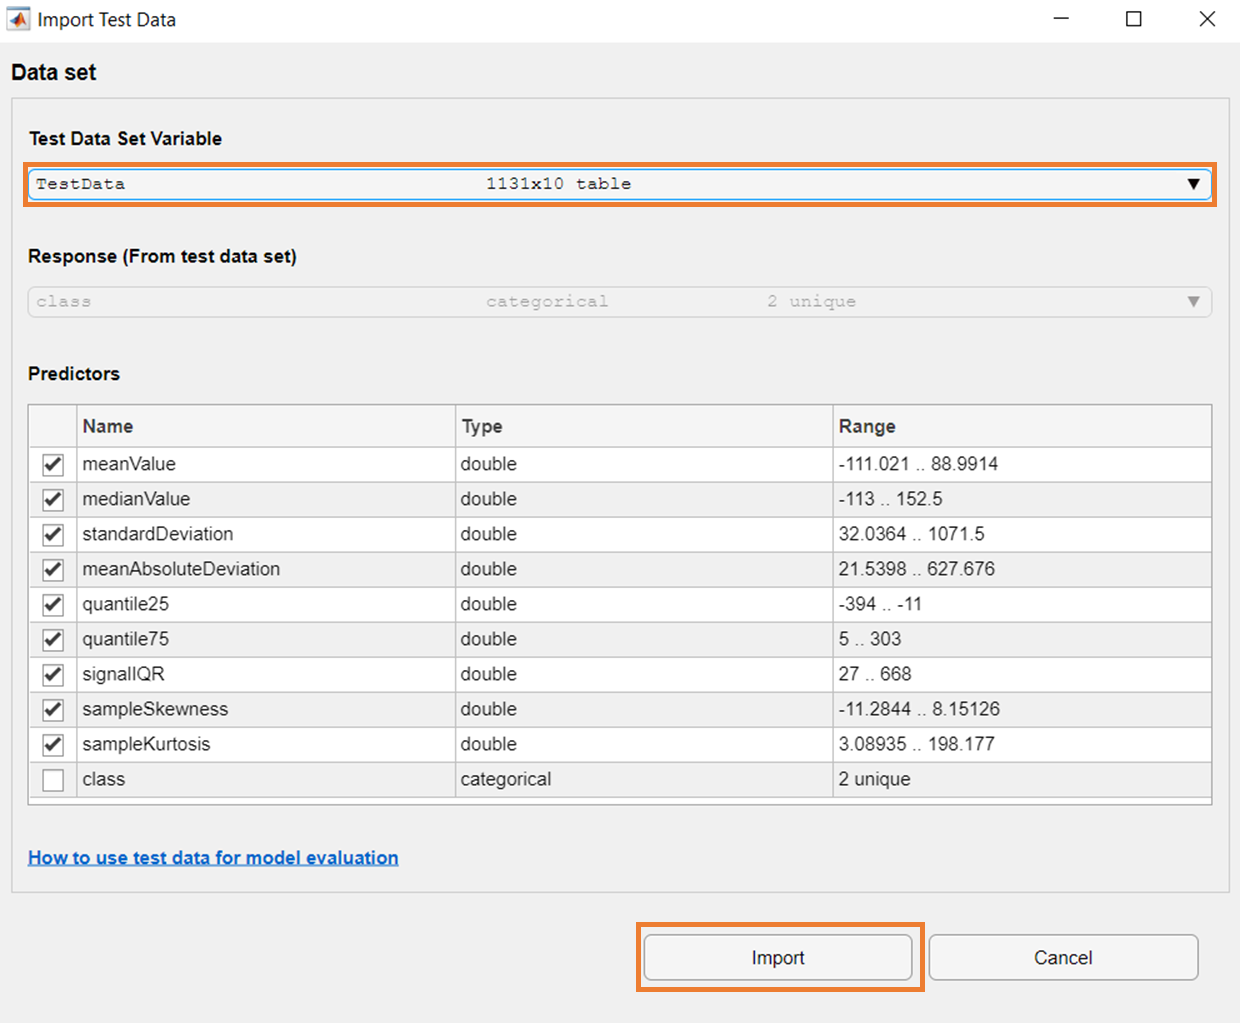

Choose a model you want to evaluate the performance of by clicking on the Star Button (Add to favorites) and click on `Test Selected` in the `Test All` dropdown menu. Alternatively, do not select any models and click on Test All (the accuracy in the Model window will change to `Accuaracy(Test)`. Your results should look similar to this:

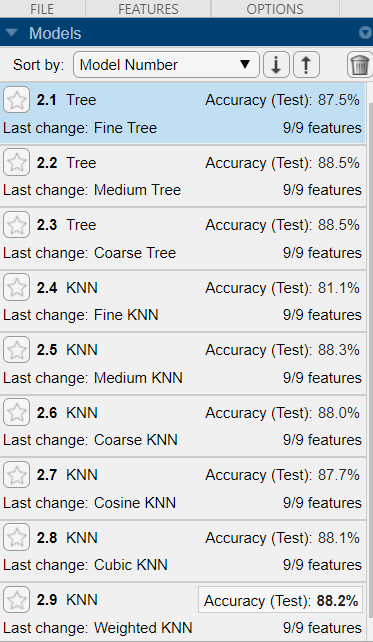

You can use the confusion matrix to visualise where the model got wrong on the test data.

As expected, the models perform very well on normal signals and misclassifies most of the afib signals. This is due to the imbalanced data set.

Note: Alternatively, you can export your trained model or generate a function for further use.

## Summary and Next steps

In this example we built machine learning models that identify heart arrhythmia from ECG waveforms. We extracted basic features applying statistical measures, interactively trained a few models with Classification Learner, and compared their performance.

Clearly we haven’t satisfactorily solved this problem, with the highest accuracy still below 90%. Here’s some additional steps you could try to improve accuracy: 

- Better features: By leveraging knowledge of the medical domain and signal processing, you can extract more powerful features. The second script `ECG_ML_FeaturesDomainKnowledge` leads you through extracting features that yield highly accurate models

- Addressing data imbalance: Your models readily misclassified abnormal ECG waveforms as normal because there are almost 10x more instances of normal ECG in the data set, but that misclassification has serious practical consequences (someone with a heart condition would not get treatment). The section above suggested two ways to address this problem, go back if you skipped it and try to balance your data.

- Hyperparameter tuning: Each models has parameters that need to be set just right to achieve optimal performance. You can have MATLAB automatically tune those hyperparameters by choosing an “Optimizable” model from the gallery in Classification Learner. This will yield a small improvement in accuracy, typically 0.5% point or less, since the default parameters settings in MATLAB are carefully chosen

## Helper Function

### Plotting Histogramm

To get started with feature extraction we first plot a histogram of both signals. We also calculate the median, [standard deviation](https://uk.mathworks.com/help/matlab/ref/std.html), [skewness](https://uk.mathworks.com/help/stats/skewness.html) and [kurtosis](https://uk.mathworks.com/help/stats/kurtosis.html) of both signals, and insert it into the plot.

function plotBothHistograms(sig_norm, sig_afib, Labels)
    mn_norm = mean(sig_norm{1,:});
    med_norm = median(sig_norm{1,:});
    std_norm = std(sig_norm{1,:});
    skew_norm = skewness(sig_norm{1,:}, 1, 2);
    k_norm = kurtosis(sig_norm{1,:}, 1, 2);
    
    mn_afib = mean(sig_afib{1,:});
    med_afib = median(sig_afib{1,:});
    std_afib = std(sig_afib{1,:});
    skew_afib = skewness(sig_afib{1,:}, 1, 2);
    k_afib = kurtosis(sig_afib{1,:}, 1, 2);
    
    str_norm = {['Mean: ', num2str(mn_norm)], ['Median: ', num2str(med_norm)], ['Std:', num2str(std_norm)], ...
        ['Skewness: ', num2str(skew_norm)], ['Kurtosis: ', num2str(k_norm)]};
    str_afib = {['Mean: ', num2str(mn_afib)], ['Median: ', num2str(med_afib)], ['Std:', num2str(std_afib)], ...
        ['Skewness: ', num2str(skew_afib)], ['Kurtosis: ', num2str(k_afib)]};
    
    tiledlayout(2,1)
    ax1 = nexttile;
    histogram(ax1, sig_norm{1,:}, 'FaceColor', 'blue');
    legend(Labels(1,:))
    text(400, 1000,str_norm);
    
    ax2 = nexttile;
    histogram(ax2, sig_afib{1,:}, 'FaceColor', 'red');
    legend(Labels(5,:))
    text(400, 1000,str_afib);
end